clear all


%%%%%%%% Блок создания массива классических каналов и квантового канала %%%%%%%%%%%
CH_NUM = 40;
CH_SPAC = 100;
 
edfa_params_paper_1;

FREQ_ARRAY = 191.6 + (1:CH_NUM) * CH_SPAC * 10 ^ (-3);

WL_ARRAY = c./(FREQ_ARRAY * 10 ^ 12) * 10 ^ 9;

WL_ARRAY = fliplr(WL_ARRAY);

% WL_ARRAY = 1530 + (1:CH_NUM) * 1 ;
% 
% FREQ_ARRAY = c./(WL_ARRAY * 10 ^ 12) * 10 ^ 9;

% FREQ_ARRAY = 192 + (1:CH_NUM) * CH_SPAC * 10 ^ (-3);
% 
% WL_ARRAY = c./(FREQ_ARRAY * 10 ^ 12) * 10 ^ 9;
% 
% WL_ARRAY = fliplr(WL_ARRAY);

%%%%%%%% Блок рассчета требований к EDFA и мощности каналов %%%%%%%%
EM_ARRAY = zeros(1,CH_NUM);
AB_ARRAY = zeros(1,CH_NUM);

for k = 1:length(WL_ARRAY)
    [EM_ARRAY(k),AB_ARRAY(k)] = get_EM_AB(WL_ARRAY(k),'EM_PAPER(1).csv','AB_PAPER(1).csv',0) ;
end
clear 'k'

%%%%%%% Блок рассчета overlap integral %%%%%%%%%%%%%%%%%%

for k = 1:length(WL_ARRAY)
    Gamma_s(k) = Function_Overlap(Fiber,WL_ARRAY(k) * 10^(-9),1);
end
clear 'k'
Gamma_p = Function_Overlap(Fiber,wl_p * 10^(-9),1);

% Gamma_s = ones(1,CH_NUM) * 0.58;
% Gamma_p = 0.62;

% for k = 1:length(WL_ARRAY)
%     v(k) = 2*pi/WL_ARRAY(k)*10^9*r_fiber*(n1^2 - n2^2)^(1/2);
%     w(k) = (0.65 + 1.619/v(k)^(3/2) + 2.879/v(k)^6)*r_fiber;
%     Gamma_s(k) = 1 - exp(-r_fiber/w(k));
% end
% clear 'k'
% 
% vp = 2*pi/wl_p*10^9*r_fiber*(n1^2 - n2^2)^(1/2);
% wp = (0.65 + 1.619/vp^(3/2) + 2.879/vp^6)*r_fiber;
% Gamma_p = 1 - exp(-r_fiber/wp);
% 
% clear 'vp' 'v' 'w' 'wp'

T = 1*10^(-3);
span = [0 T];
y0 = 0;

%%%%%%%%%%%%%%%%%%%% Multi wavelength model %%%%%%%%%%%%%%%
%%%%%% Условия приемника %%%%%%%%%%%%

P_min = - 23; %dBm
OSNR_min = 9; %dB
IL = 8; % потери в приемнике dBm
Rx = - 23; % чувствительность приемника dBm

%%%%%%%%% PARAMS PART %%%%%%%%%%%%%%%%%%%%%%
P_p_0 = 18; %dBm
P_s_in_0 = Rx + IL; %dBm
P_s_const = -25; %используемая мощность сигнала для зависимости от длины

Losses = 10 ^ (( IL ) / 10);

delta_P = -1;
delta_P_p = 0.5;
M = 500; %число рассматриваемых длин усилителя
N = 11; % число рассматриваемых мощностей сигналов
K = 30; % число рассметриваемых мощностей накачки
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

P_s_in_ARRAY = zeros(1,N);
P_p = zeros(1,K);
L_ARRAY = zeros(1,M);
P_s_dBm = zeros(1,N);
P_p_dBm = zeros(1,K);
P_gr = zeros(1,CH_NUM);
OSNR_gr = zeros(1,CH_NUM);
OBW = zeros(1,CH_NUM);




for k = 1:length(WL_ARRAY)
    OBW(k) = BWNmToGHz(BW * 10^(-9),WL_ARRAY(k) * 10^(-9)) ;% Частотное пропускание детектора
end
clear 'k'

for g = 1:N  
    P_s_dBm(g) = P_s_in_0 + delta_P * (g-1);
    P_s_in_ARRAY = 10 .^ (( P_s_dBm ) ./ 10) ./ 1000;
end
clear 'g'

for g = 1:K  
    P_p_dBm(g) = P_p_0 + delta_P_p * (g-1);
    P_p(g) = 10 .^ (( P_p_dBm(g) ) ./ 10) ./ 1000;
end
clear 'g'

for k = 1:length(WL_ARRAY)
    OSNR_gr(k) = OSNR_min;
    P_gr(k) = P_min;
end
clear 'k'

for g = 1:M
    L_ARRAY(g) = (g-1)/10;
end
clear 'g'

P_s = 10 ^ (( P_s_const ) / 10) / 1000;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%% Блок поиска оптимальной мощности %%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%% Рассчет зависимости усиления от длины усилителя %%%%%%%

for k = 1:K
    

    GAIN = zeros(N,CH_NUM);
    GAIN_L = zeros(M,CH_NUM);
    N_sp = zeros(N,CH_NUM);
    P_ASE = zeros(N,CH_NUM);
    OSNR = zeros(N,CH_NUM);
    MEDIUM = zeros(1,CH_NUM);
    DELTA_M = zeros(1,CH_NUM);
    P_out = zeros(1,CH_NUM);
    P_on_detector = zeros(1,CH_NUM);

    for g = 1:M
        
        
        [t_m , N2_m] = ode15s(@(t_m,N2_m) edfa_eqs_paper_1(t_m,N2_m,L_ARRAY(g),EM_ARRAY,AB_ARRAY,WL_ARRAY,P_p(k),P_s,CH_NUM,Gamma_s,Gamma_p) ,span,y0);
           
        for u = 1:length(WL_ARRAY)
        
            GAIN_L(g,u) = exp(Gamma_s(u) * (EM_ARRAY(u) + AB_ARRAY(u)) / (4.3429 * rho * A) * N2_m(length(t_m)) - Gamma_s(u) * AB_ARRAY(u) * L_ARRAY(g) / 4.3429);
        
        end    
    end
    
    clear 'g' 'u' 't_m' 'N2_m'
    
    
    for g = 1:M
        MEDIUM(g) = sum(GAIN_L(g,:)) / CH_NUM;
    end
    
    clear 'g'
    
    for g = 1:M
        DELTA_M(g) = 0;
        for u = 1:CH_NUM
            for s = 1:CH_NUM
                if GAIN_L(g,u) - GAIN_L(g,s) > DELTA_M(g)
                   DELTA_M(g) = GAIN_L(g,u) - GAIN_L(g,s);
                end
            end
        end
    end
    clear 'g' 's'
    
    
    index_top = [];
    for g = 1:M
        if MEDIUM(g) > max(MEDIUM)/2
        index_top(end+1) =  g; % Это список индексов столбцов усилений по длинам волн, где среднее значение усиления больше чем половина максимального
        end
    end
    clear 'g'
    
    delta_opt = DELTA_M(index_top(1));
    
    I = 1;
    for g = 1:length(index_top)
        if DELTA_M(index_top(g)) < delta_opt
            delta_opt = DELTA_M(index_top(g));
            I = index_top(g);
        end
    end
    clear 'g'
    
    [m,II] = max(MEDIUM);
    
%     'Оптимальная для наибольшего общего усиления длина m'
%     L_ARRAY(II)
    
    
    L = L_ARRAY(II);
    
    
    for g = 1:N
            
        [t_m , N2_m] = ode15s(@(t_m,N2_m) edfa_eqs_paper_1(t_m,N2_m,L,EM_ARRAY,AB_ARRAY,WL_ARRAY,P_p(k),P_s_in_ARRAY(g),CH_NUM,Gamma_s,Gamma_p) ,span,y0);
           
           for u = 1:length(WL_ARRAY)
        
               GAIN(g,u) = exp(Gamma_s(u) * (EM_ARRAY(u) + AB_ARRAY(u)) / (4.3429 * rho * A) * N2_m(length(t_m)) - Gamma_s(u) * AB_ARRAY(u) * L / 4.3429);
               
               N_sp(g,u) = N2_m(length(t_m)) / ( N2_m(length(t_m)) - AB_ARRAY(u)/EM_ARRAY(u) * (rho*L*A - N2_m(length(t_m))));
               
               P_ASE(g,u) = 2 * h * c / (WL_ARRAY(u) * 10^(-9)) * N_sp(g,u) * OBW(u) * (GAIN(g,u) - 1);
               
               P_out(g,u) = P_s_in_ARRAY(g) * GAIN(g,u);
               
               P_on_detector(g,u) = P_s_in_ARRAY(g) * GAIN(g,u) / Losses ;
    
               OSNR(g,u) = (P_on_detector(g,u))/(P_ASE(g,u) / Losses);
              
           end
           p_on_detector(g,k) = P_on_detector(g,22);
           p_ase(g,k) = P_ASE(g,22);
           osnr(g,k) = OSNR(g,22);
           gain(g,k) = GAIN(g,22);
    end   
    clear 'g' 'u'
    
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%% Блок поиска оптимальной мощности %%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    P_optimal(k) = Rx + IL;
    
    index_opt_power_osnr = [];
    for g = 1:N
        if 10*log10(OSNR(g,:)) >= OSNR_min
            index_opt_power_osnr(end+1) = g;
        end
    end
    clear 'g' 
    
    index_opt_power_detect = [];
    for g = 1:N
        if 10*log10(P_on_detector(g,:)*1000) >= Rx
            index_opt_power_detect(end+1) = g;
        end
    end
    clear 'g' 
    
    for g = 1:length(index_opt_power_osnr)
        for r = 1:length(index_opt_power_detect)
            if P_s_dBm(index_opt_power_osnr(g)) < P_optimal(k) && index_opt_power_osnr(g) == index_opt_power_detect(r)
               P_optimal(k) = P_s_dBm(index_opt_power_osnr(g)); 
            end
        end
    end
    clear 'g' 'r'
    
    clear 'MEDIUM' 'DELTA_M' 'delta_opt' 'index_top' 'm' 'I' 'II' 'L' 'index_opt_power_osnr' 'index_opt_power_detect'
    clear 'GAIN_L' 'GAIN' 'P_ASE' 'N_sp' 'P_out' 'P_on_detector' 'OSNR' 't_m' 'N2_m'
    K - k
end

ans = 29

ans = 28

ans = 27

ans = 26

ans = 25

ans = 24

ans = 23

ans = 22

ans = 21

ans = 20

ans = 19

ans = 18

ans = 17

ans = 16

ans = 15

ans = 14

ans = 13

ans = 12

ans = 11

ans = 10

ans = 9

ans = 8

ans = 7

ans = 6

ans = 5

ans = 4

ans = 3

ans = 2

ans = 1

ans = 0

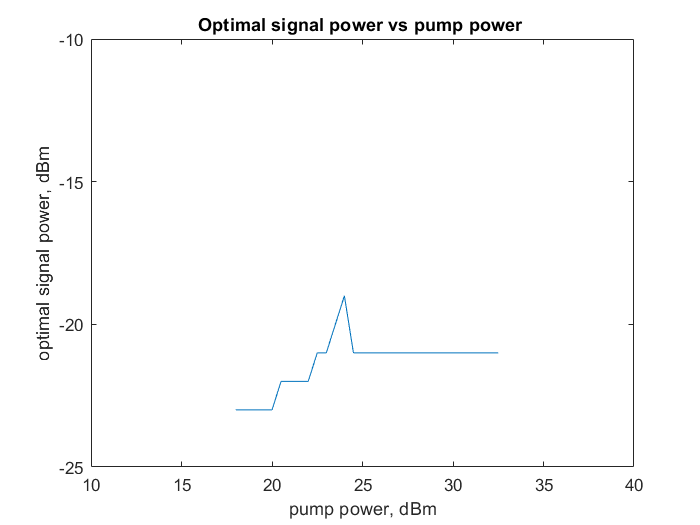

figure(1)
plot(P_p_dBm,P_optimal)
title('Optimal signal power vs pump power ')
ylabel('optimal signal power, dBm')
xlabel('pump power, dBm')
axis([10 40 -25 -10])

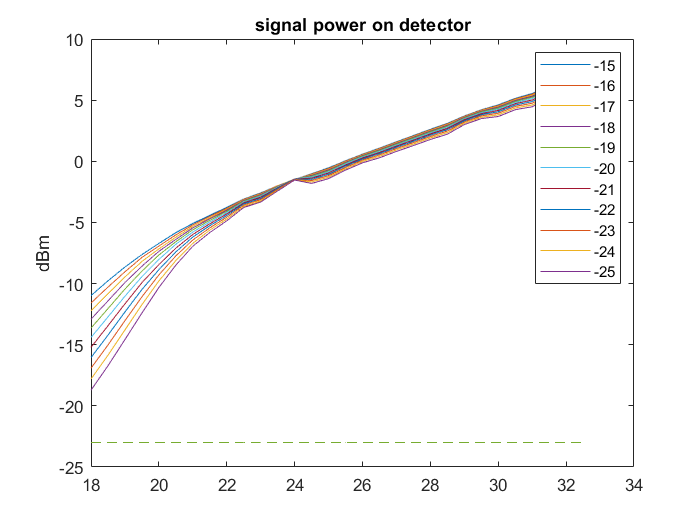


figure(2)
for g = 1:N
    plot(P_p_dBm,10*log10(p_on_detector(g,:) * 1000))
    hold on
end
plot(P_p_dBm,ones(1,K)*P_min,'--')
legend(string(P_s_dBm))
title('signal power on detector')
ylabel('dBm')

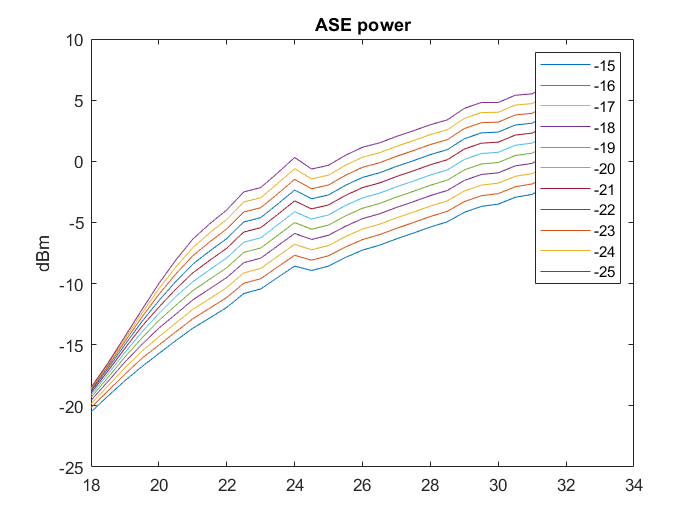


figure(3)
for g = 1:N
    plot(P_p_dBm,10*log10(p_ase(g,:) * 1000))
    hold on
end
legend(string(P_s_dBm))
title('ASE power')
ylabel('dBm')

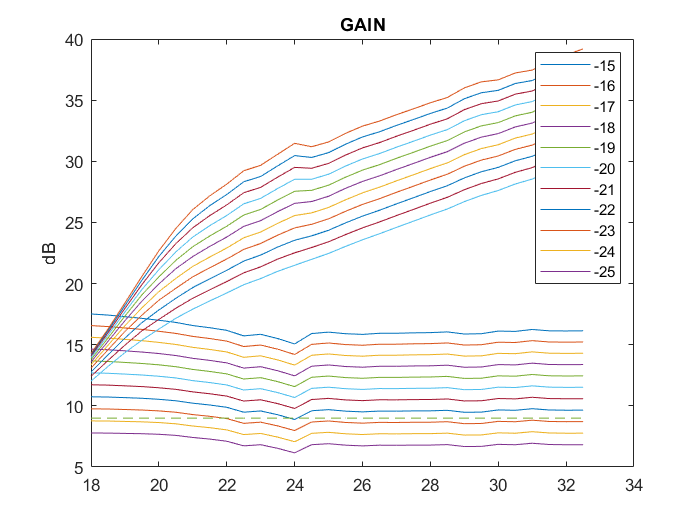


figure(4)
for g = 1:N
    plot(P_p_dBm,10*log10(osnr(g,:)))
    hold on
end
plot(P_p_dBm,ones(1,K)*OSNR_min,'--')
title('OSNR')
legend(string(P_s_dBm))
ylabel('dB')

figure(4)
for g = 1:N
    plot(P_p_dBm,10*log10(gain(g,:)))
    hold on
end

title('GAIN')
legend(string(P_s_dBm))
ylabel('dB')